# Extract epoch-level features for time windows

Sam Michalka

This script will help you extract features for machine learning from EEG data that has already been preprocessed and epoched. It stores the data in a Matlab table, which can then be written to a csv or used to do ML in Matlab. 

## Set up your data and parameters

This code requires that you have eeglab installed to do frequency power extraction (you could do this with regular matlab commands like pwelch instead if you want). The line below checks to see if it is already open, and if not, it starts eeglab.

if ~exist('pop_loadset') || ~exist("ALLEEG",'var') %#ok<EXIST>
    [ALLEEG EEG CURRENTSET ALLCOM] = eeglab;
end 

For frequency band analysis, we list the desired frequency bands here. You can edit this to exclude some bands if you're not interested in them.

freqBands = table(["delta","theta","alpha","beta","lowerAlpha","upperAlpha","lowerBeta","upperBeta"]',...
    [1 4 8 12.5 8 10 12.5 20]', ...
    [4 8 13 30 11 13 20 30]','VariableNames',{'Names','LowFreq','HighFreq'})


Create a list of all of the files that you want to include in your analysis. This expects one .set file per subject. Change the stuff in "" to match your file location and names. The * allows you to list all the files of a certain type.

subjNames = {'A02','A04','A05','A07','A08','A10','A11','A12','A13','A14','A15','A16','A17','A18','A19','A20','A21','A22','A23','A24','A27','A28'};
conditions  = {'blank_1','blank_2','blank_3','prob_1','prob_2','prob_3'}%,'feedback_1','feedback_2','feedback_3'}; % conditions to extract

dir_data = '../nback_study_VR_EEG_data/';
filename_root = '_upevent_mark_PreprocDAllEpoch.set';

%lsout = dir("../nback_study_VR_EEG_data/*/*_upevent_mark_PreprocDAllEpoch.set"); % all subjects

## Extract all of the values for each subject and put in a table

This is the main code and will take a little while to run. If you want to just test it on one or two people, you can change the line below to "for s = 1:2"

% Loop through all subjects.
for s = 1:length(subjNames)
    subjName = subjNames{s}; 
    EEG = pop_loadset(strcat(dir_data,subjName,'/',subjName,filename_root));

    chtable = struct2table(EEG.chanlocs);

    % Extract the spectopo values for each trial
    allfreqs = [];
    badtrials = [];
    % The output number of frequencies is 126 by default, so it's hard
    % coded in here. You may need to change this for other data.
    spectraByEpoch = zeros(size(EEG.data,1),126,size(EEG.data,3)); % channels, frequencies, epochs
    absolutePowerByEpoch = zeros(size(EEG.data,1),height(freqBands),size(EEG.data,3)); % channels, bands, epochs



Loop through each epoch and calcuate the absolute power

    for ut = 1:size(EEG.data,3)



Calcuate the absolute power for each epoch

       [spectra,freqs] =  spectopo(EEG.data(:,:,ut),0,EEG.srate,'freqrange',[1 30],'plot','off');

       absolutePowerByEpoch(:,:,ut) = getAbsolutePower(spectra,freqs,freqBands);
       spectraByEpoch(:,:,ut) = spectra;


Store the epoch-level data in a table, which will then be combined with other tables. [There are more efficient ways to write this, but this works for now.]

        % Put these into a table
        temptbl  = array2table(absolutePowerByEpoch(:,:,ut),"VariableNames",freqBands.Names);
        temptbl.id = repmat(EEG.subject,height(temptbl),1);
        temptbl.channel = (1:size(EEG.data,1))';
        temptbl.channelname = string(chtable.labels);
        temptbl.epoch = ut  .* ones(height(temptbl),1);
        temptbl.trial = EEG.event(ut).trialnum .* ones(height(temptbl),1);
        temptbl.type = repmat(string(EEG.event(ut).type),height(temptbl),1);


Here is where to put other code to extract more features from each epoch.  The shape of this data should be channels x 1 for a single feature. You can then add it to the table by:

temptbl.myfeature = myValues; % where my values are ch x 1.

You can also do this in more complex ways if desired.

Make a table for the current subject and concatenate epoch after epoch to store the data.

        if ut == 1
            subjtbl = temptbl;
        else
            % concatenate the tables
            subjtbl = [subjtbl; temptbl];
        end
    end

Store the data in a large table for every subject and epoch.

    if s == 1
        epoch_data = subjtbl;
    else
        epoch_data = [epoch_data; subjtbl];
    end
    
end


### Save Trial Data to CSV

epoch_data.channelnames = cell2mat(epoch_data.channelname);
epoch_data.channelnames = categorical(epoch_data.channelnames)
writetable(epoch_data,"NBackMLFeaturesEpoch.csv")



Plot some results

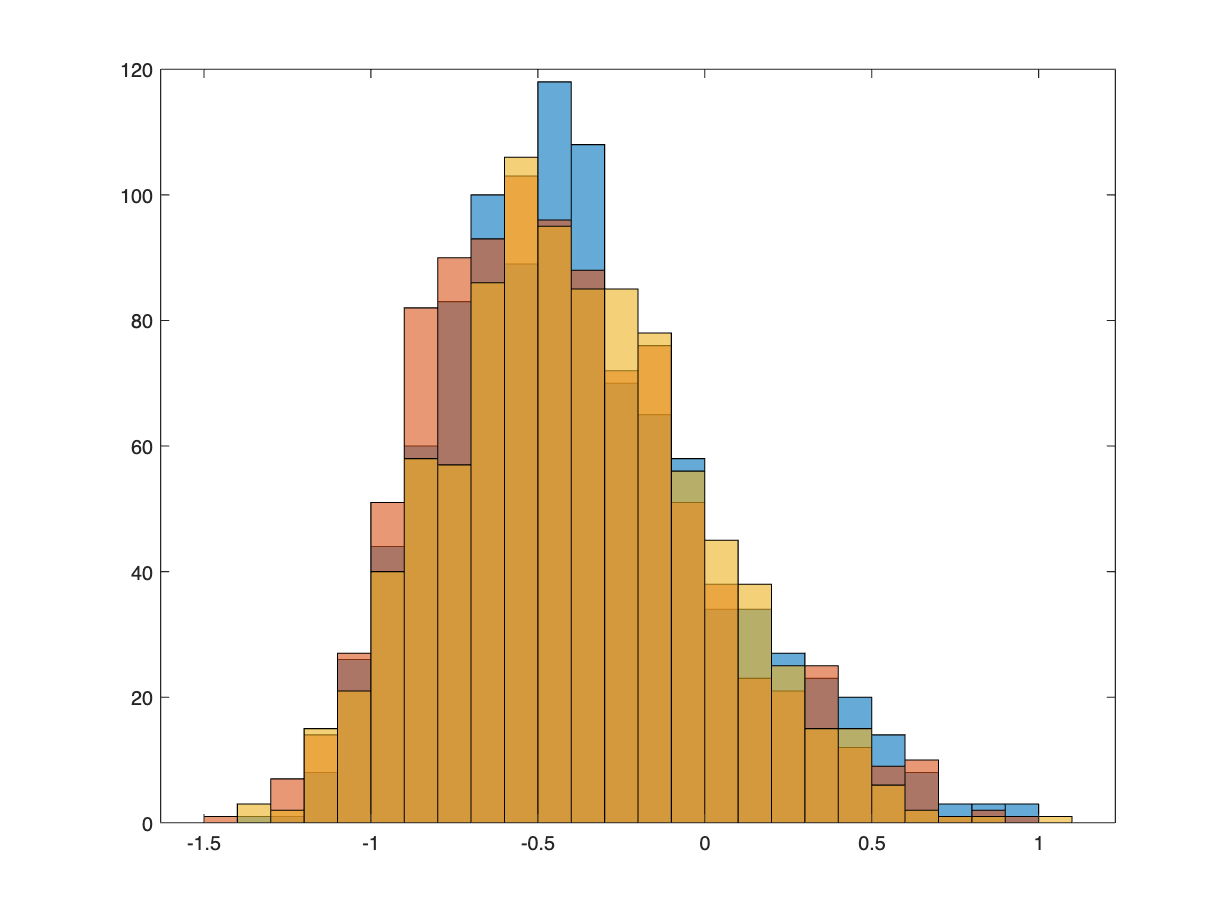

clear
epoch_data = readtable("NBackMLFeaturesEpoch.csv");
figure; histogram(log10(epoch_data(epoch_data.type=="blank_1" & epoch_data.channel==4,:).alpha))
hold on; histogram(log10(epoch_data(epoch_data.type=="blank_2" & epoch_data.channel==4,:).alpha))
hold on; histogram(log10(epoch_data(epoch_data.type=="blank_3" & epoch_data.channel==4,:).alpha))

# Helper functions

### Calculate absolute power from the spectra for frequency bands of interest. 

function [absolutePower] = getAbsolutePower(spectra,freqs,freqBands)
% Put in a 2d spectra (ch x freqs), get out 2d matrix of ch x bandpowers
    absolutePower = zeros(size(spectra,1),height(freqBands));
    for b = 1:height(freqBands)
        % find the index of the frequencies between those values
        % (non-inclusive)
        freqIdx = find(freqs> freqBands.LowFreq(b) & freqs<freqBands.HighFreq(b));
        if isempty(freqIdx)
            !warning("No frequencies fall within the range, make band larger. It is non-inclusive.")
        end
        % Convert spectra to mean absolute power 
        if size(size(spectra),2) == 2
            absolutePower(:,b) = mean(10.^(spectra(:,freqIdx)/10),2);
        elseif size(size(spectra),2) == 3

        else
            !warning("Too many dimensions bro")
        end
    end
end
